Color differences of 24 patches in four different modes of Spyder X

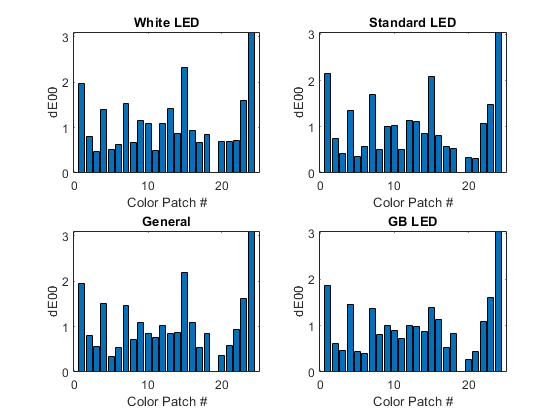

modename = {'White LED','Standard LED','General','GB LED'};

dEall = zeros(4,24);

clf
for mode = 1:4
    colstart = (mode-1)*3 + 1;

    cc = ColorConversionClass;
    load('spyder_rift','spyder')
    XYZ_cck = spyder(:,colstart:colstart+2);
    LAB_cck = cc.XYZ2lab(XYZ_cck,XYZ_cck(19,:));

    load('colorchecker_test_result_rift')
    spec = zeros(24,41);
    for i = 1:24
        s = spd_ol490_24{i};
        s = s(1:10:end);
        spec(i,:) = s;
    end

    % XYZ is 24x3
    XYZ_ol490 = cc.spd2XYZ(spec');
    LAB_ol490 = cc.XYZ2lab(XYZ_ol490,XYZ_ol490(19,:));

    for i = 1:24
        [dE00 dE94 dEab] = cc.LAB2dE(LAB_cck(i,:)',LAB_ol490(i,:)');
        dE(i) = dE00;
        dEall(mode,:) = dE;
    end

    subplot(2,2,mode)
    bar(dE)
    xlabel('Color Patch #')
    ylabel('dE00')
    title(modename{mode})
end

dEmean = mean(dEall,2);
dEstd = std(dEall,1);

saveas(gcf,'compare_dE_2x2.png')

Color differences of 24 patches in four different modes of Spyder X, consolidated

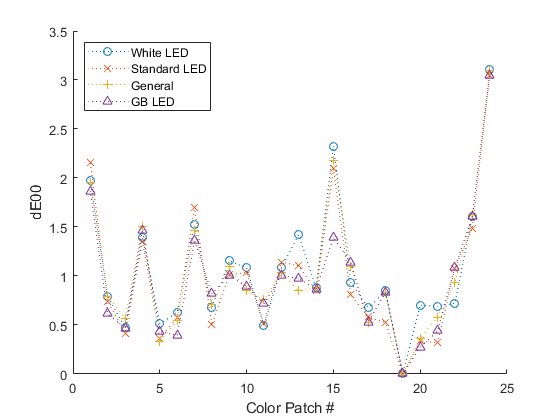

clf
hold on
plot(dEall(1,:),'o:')
plot(dEall(2,:),'x:')
plot(dEall(3,:),'+:')
plot(dEall(4,:),'^:')
xlabel('Color Patch #')
ylabel('dE00')
legend('White LED','Standard LED','General','GB LED')
legend('Location','northwest')

saveas(gcf,'compare_dE.png')

(3D) Comparison of chromaticity in different modes (circle: reference, cross: Spyder X)

mode = 2

mode = 2

colstart = (mode-1)*3 + 1;

cc = ColorConversionClass

cc =   ColorConversionClass with properties:

    Property1: []


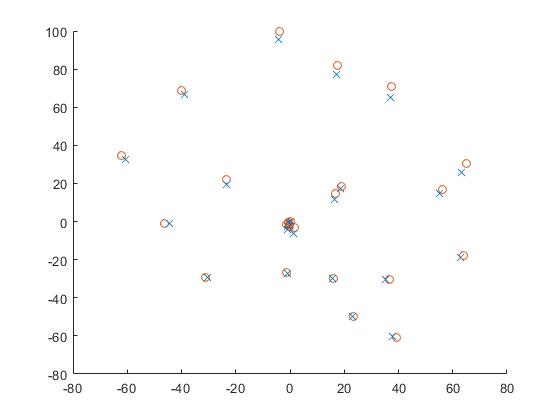

load('spyder_rift','spyder')
XYZ_cck = spyder(:,colstart:colstart+2);
LAB_cck = cc.XYZ2lab(XYZ_cck,XYZ_cck(19,:));

clf
hold on
plot3(LAB_cck(:,2),LAB_cck(:,3),LAB_cck(:,1),'x')
plot3(LAB_ol490(:,2),LAB_ol490(:,3),LAB_ol490(:,1),'o')

Comparison of chromaticity in different modes (circle: reference, cross: Spyder X)

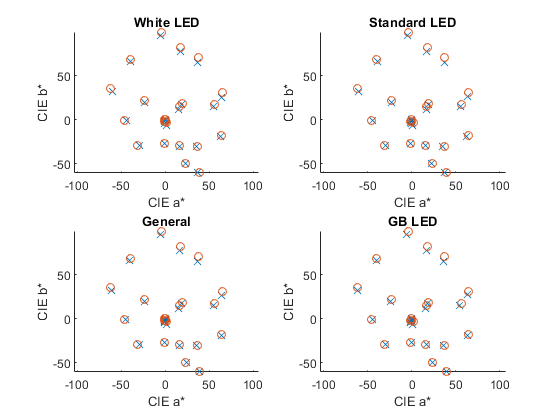

clf

for mode = 1:4
    colstart = (mode-1)*3 + 1;

    cc = ColorConversionClass;
    load('spyder_rift','spyder')
    XYZ_cck = spyder(:,colstart:colstart+2);
    LAB_cck = cc.XYZ2lab(XYZ_cck,XYZ_cck(19,:));


    subplot(2,2,mode)
    hold on
    plot(LAB_cck(:,2),LAB_cck(:,3),'x')
    plot(LAB_ol490(:,2),LAB_ol490(:,3),'o')
    xlabel('CIE a*')
    ylabel('CIE b*')
    % legend('Spyder X','Spectrometer')
    axis equal
    title(modename{mode})
end
saveas(gcf,'compare CIEab.png')

Linearity of luminance measurements in different modes

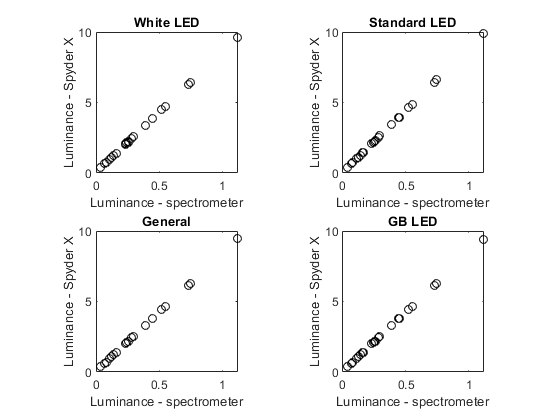

clf
hold on
symb = 'ox+^';

for mode = 1:4
    colstart = (mode-1)*3 + 1;

    cc = ColorConversionClass;
    load('spyder_rift','spyder')
    XYZ_cck = spyder(:,colstart:colstart+2);

    Y_cck = XYZ_cck(:,2);
    Y_ol490 = XYZ_ol490(:,2);

    subplot(2,2,mode)
    plot(Y_ol490*1000,Y_cck,'ok')
    xlabel('Luminance - spectrometer')
    ylabel('Luminance - Spyder X')
    title(modename{mode})
    axis square
end

saveas(gcf,'compare_luminancex4.png')